load('Detector.mat');
img = testimage;
[bbox,scores]=detect(detector,img)

bbox =          588         277         130         130
        1589         967         169         169
        1555        1036         200         200
         322         298         260         260
         783         164         309         309
        1087         355         476         476
        1262         195         518         518


scores =    11.7559
    2.4130
   31.5873
   66.8059
    6.6082
    8.2819
   18.8296


[a,b]=max(scores)

a = 66.8059

b = 4


annotation=sprintf('Ball_Confidence = %.1f',scores(b))

annotation = 'Ball_Confidence = 66.8'

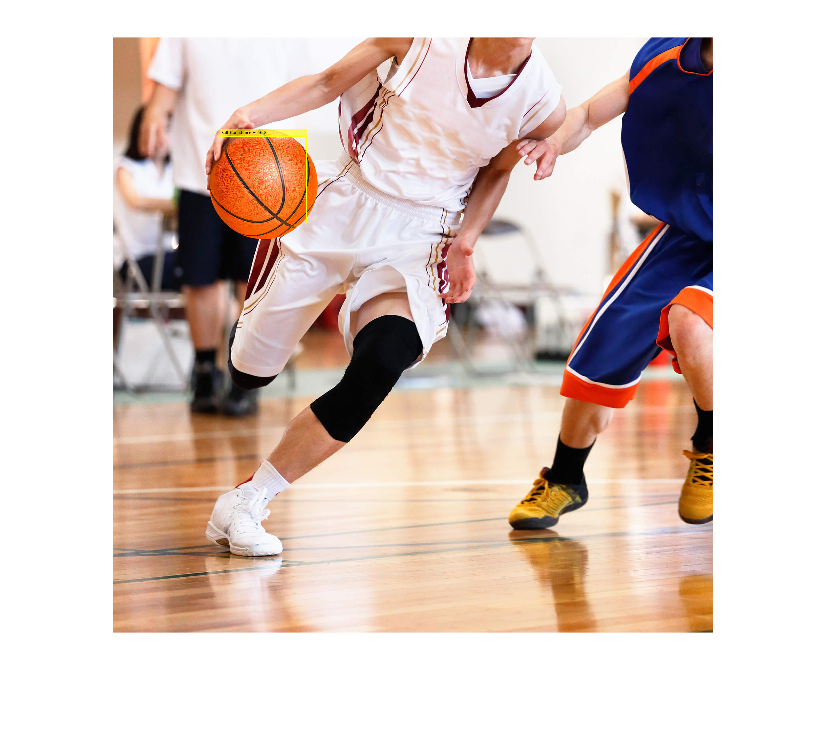

img=insertObjectAnnotation(img,'rectangle',bbox(b,:),annotation);

figure
imshow(img)